# 8per

T2_spinspin18 = readtable('8per.xlsx','Sheet','T2_spinspin');

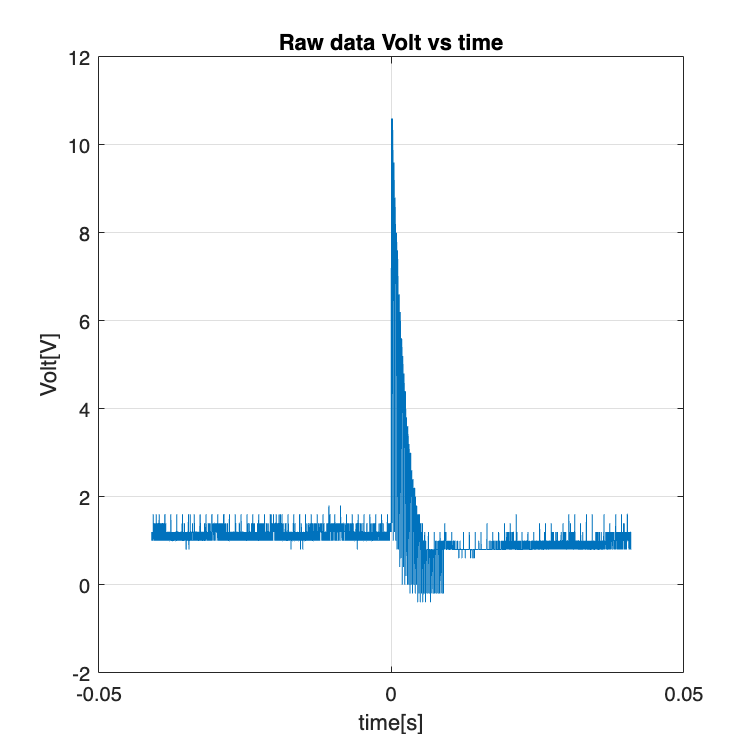

figure;
set(gcf,'position',[0,0,1000,1000])
time8=T2_spinspin18.Time;
Volt8 = T2_spinspin18.CHAN1;

plot(time8,Volt8)
ylabel('Volt[V]')
xlabel('time[s]')

grid on
title('Raw data Volt vs time')




% 
% k = find(time>0);
% time=time(k);
% Volt=Volt(k);






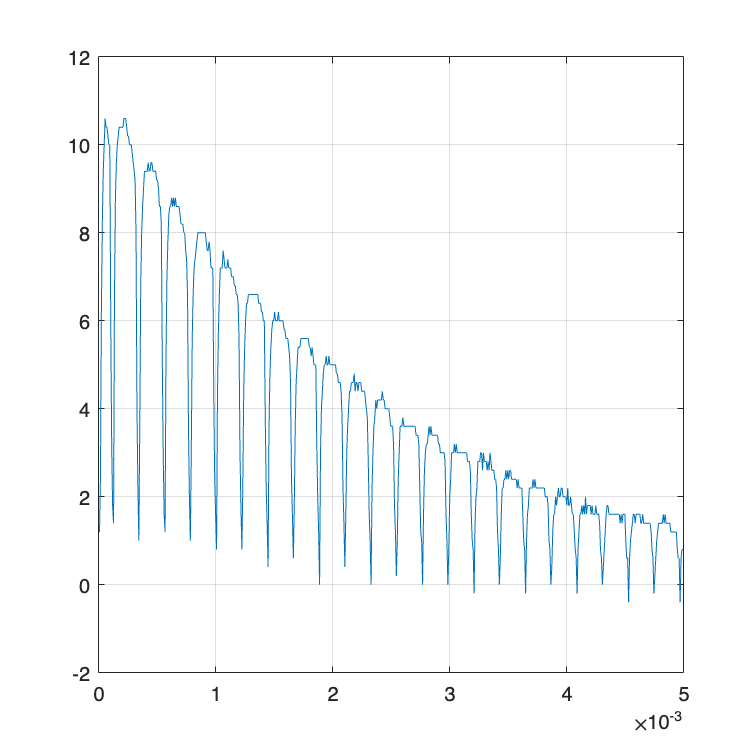


time_start =0;
time_end = 0.005;

k = find((time8>time_start)&(time8 < time_end));
time8=time8(k);
Volt8=Volt8(k);




%k = find((Volt>0));
%time=time(k);
%Volt=Volt(k)-min(Volt);



%Volt = smooth(Volt);
plot(time8,Volt8)


grid on

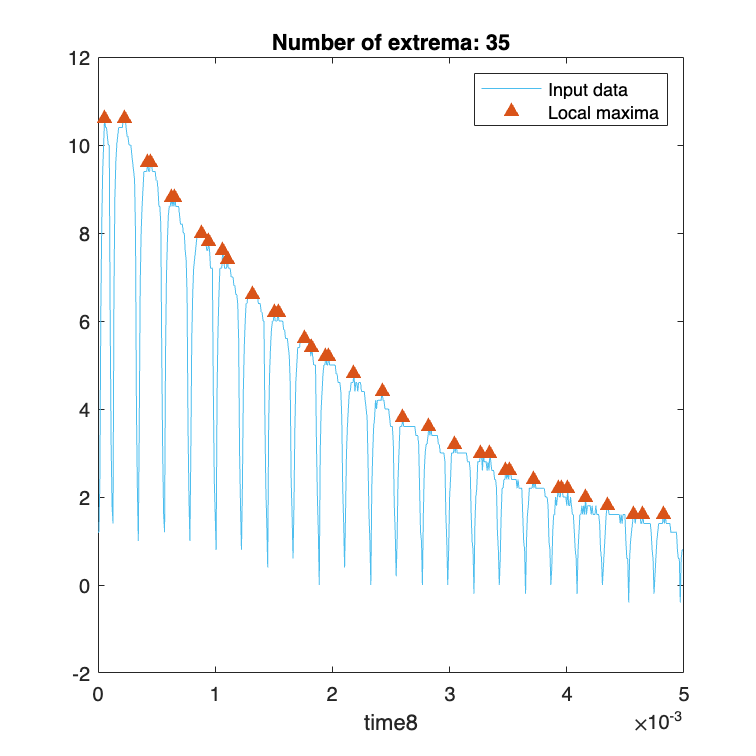

% Find local maxima
maxIndices8 = islocalmax(Volt8,"MinSeparation",2e-05,"MaxNumExtrema",35,...
    "SamplePoints",time8);

% Display results
clf
plot(time8,Volt8,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(time8(maxIndices8),Volt8(maxIndices8),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices8))
hold off
legend
xlabel("time8")

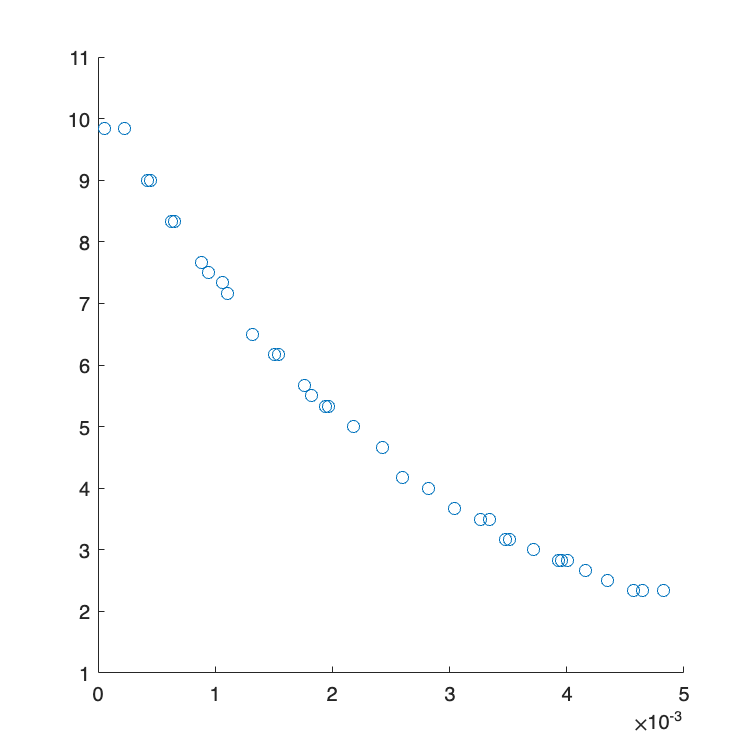

time8 = time8(maxIndices8);
Volt8 = Volt8(maxIndices8);

delta_y=Volt8.*0+1/12^0.5;
delta_x=time8.*0+0.001/12^0.5;

x=time8;
y=Volt8;


T8 = table(x,delta_x,y,delta_y);
writetable(T8,'T2_8_spinspin_err.xlsx') 



scatter(time8,Volt8)

% T2_spinspin_cap(time,Volt)
%[fitresult, gof]

# 4per

T2_spinspin14 = readtable('4per.xlsx','Sheet','T2_spinspin');

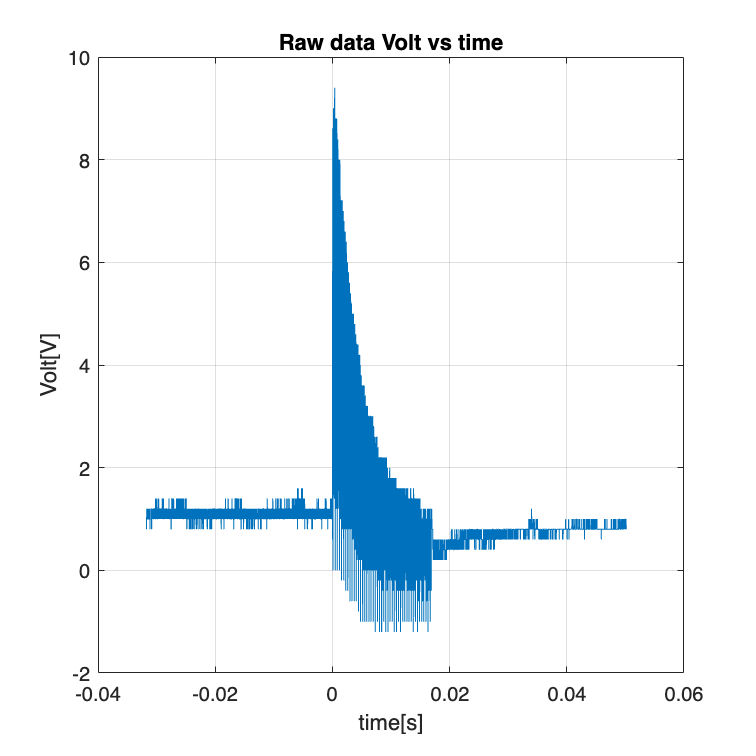

figure;
set(gcf,'position',[0,0,1000,1000])
time4=T2_spinspin14.Time;
Volt4 = T2_spinspin14.CHAN1;

plot(time4,Volt4)
ylabel('Volt[V]')
xlabel('time[s]')
title('Raw data Volt vs time')
grid on



% 
% k = find(time>0);
% time=time(k);
% Volt=Volt(k);



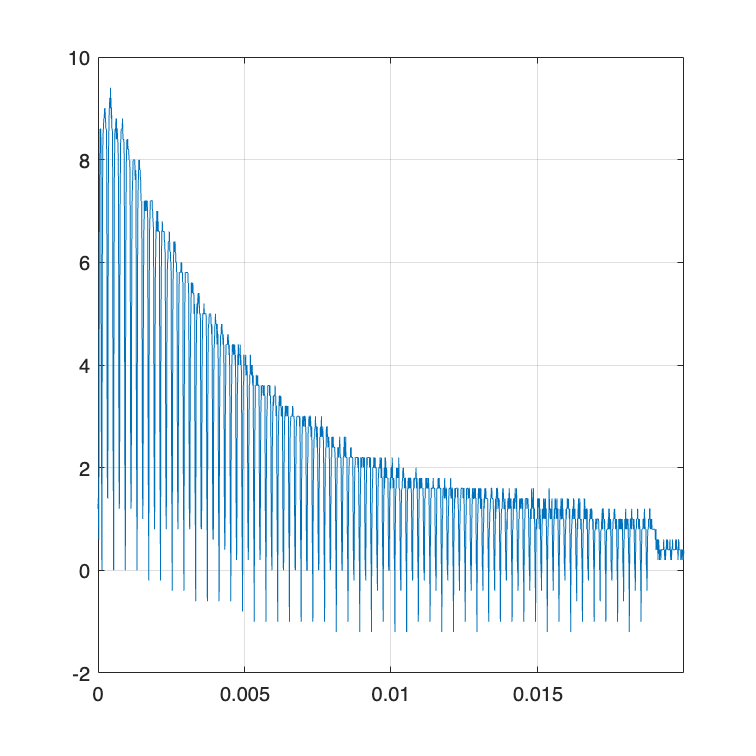


time_start =0;
time_end = 0.018;

k = find((time4>time_start)&(time4 < time_end));
time4=time4(k);
Volt4=Volt4(k);




%k = find((Volt>0));
%time=time(k);
%Volt=Volt(k)-min(Volt);



%Volt = smooth(Volt);
plot(time4,Volt4)


grid on

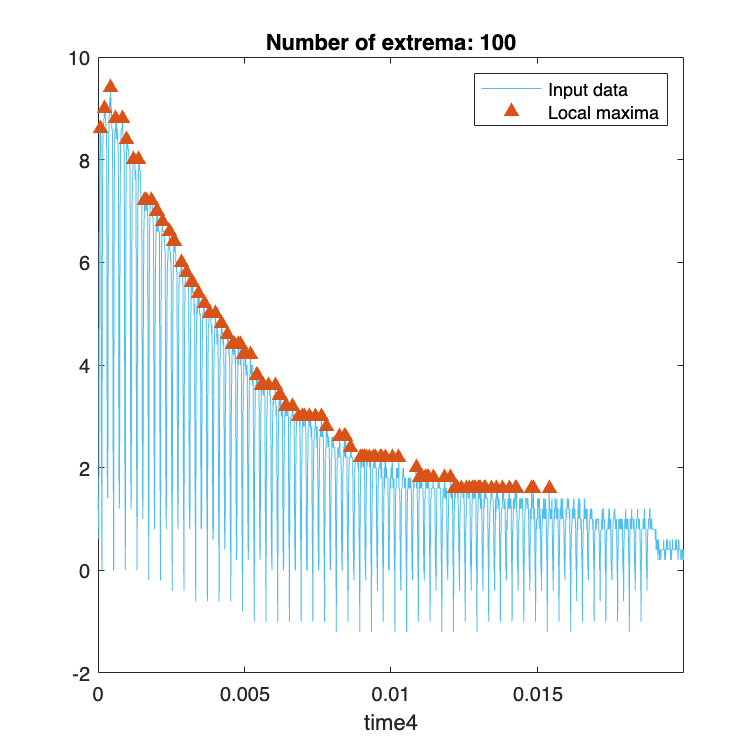

% Find local maxima
maxIndices4 = islocalmax(Volt4,"MinSeparation",2e-05,"MaxNumExtrema",100,...
    "SamplePoints",time4);

% Display results
clf
plot(time4,Volt4,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(time4(maxIndices4),Volt4(maxIndices4),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices4))
hold off
legend
xlabel("time4")

time4 = time4(maxIndices4);
Volt4 = Volt4(maxIndices4);
delta_y=Volt4.*0+1/12^0.5;
delta_x=time4.*0+0.001/12^0.5;
x=time4;
y=Volt4;
T4 = table(x,delta_x,y,delta_y)

T4 = 100×4 table
        x          delta_x       y     delta_y
    __________    __________    ___    _______

    7.2001e-05    0.00028868    8.6    0.28868
        0.0002    0.00028868      9    0.28868
      0.000384    0.00028868    9.4    0.28868
      0.000552    0.00028868    8.8    0.28868
      0.000752    0.00028868    8.8    0.28868
      0.000888    0.00028868    8.4    0.28868
      0.001104    0.00028868      8    0.28868
      0.001256    0.00028868      8    0.28868
      0.001424    0.00028868    7.2    0.28868
       0.00148    0.00028868    7.2    0.28868
      0.001632    0.00028868    7.2    0.28868
      0.001808    0.00028868      7    0.28868
      0.001832    0.00028868      7    0.28868
      0.001976    0.00028868    6.8    0.28868
      0.002192    0.00028868    6.6    0.28868
      0.002328    0.00028868    6.4    0.28868


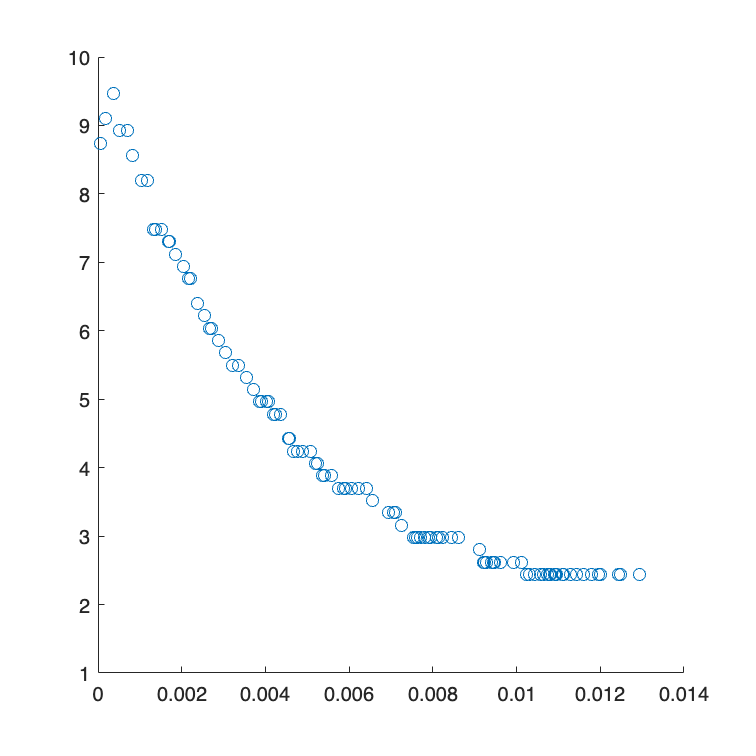

% writetable(T4,'T2_4_spinspin_err.xlsx') 



scatter(time4,Volt4)

% T2_spinspin_cap(time,Volt)
%[fitresult, gof]

# 2per

T2_spinspin12 = readtable('2per.xlsx','Sheet','T2_spinspin')

T2_spinspin12 = 10240×2 table
      Time       CHAN1
    _________    _____

     -0.02984    0.08 
    -0.029832    0.08 
    -0.029824    0.08 
    -0.029816    0.08 
    -0.029808    0.08 
      -0.0298       0 
    -0.029792       0 
    -0.029784       0 
    -0.029776       0 
    -0.029768       0 
     -0.02976    0.08 
    -0.029752       0 
    -0.029744       0 
    -0.029736       0 
    -0.029728    0.08 
     -0.02972    0.08 


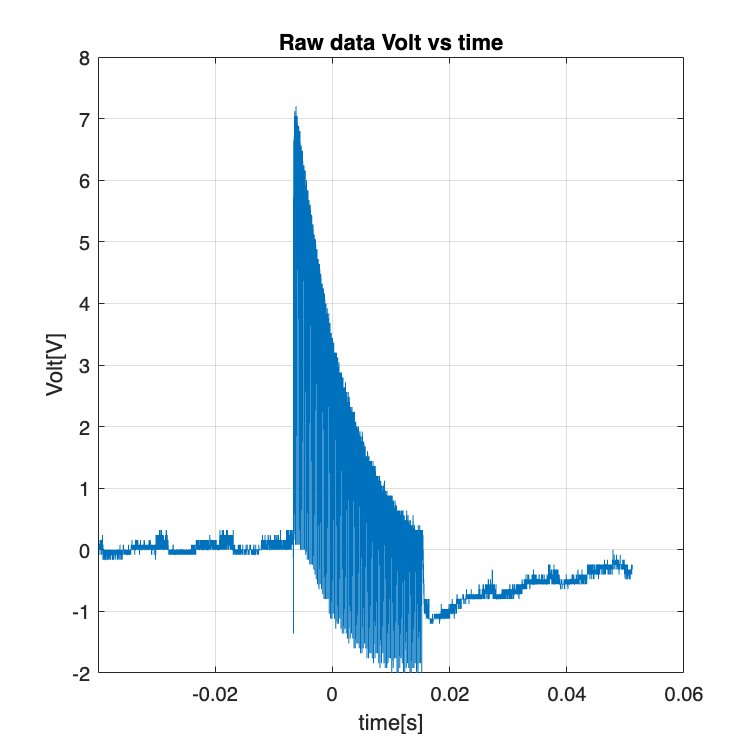

figure;
set(gcf,'position',[0,0,1000,1000])
time2=T2_spinspin12.Time;
Volt2 = T2_spinspin12.CHAN1;

plot(time2,Volt2)
ylabel('Volt[V]')
xlabel('time[s]')
title('Raw data Volt vs time')
grid on



% 
% k = find(time>0);
% time=time(k);
% Volt=Volt(k);



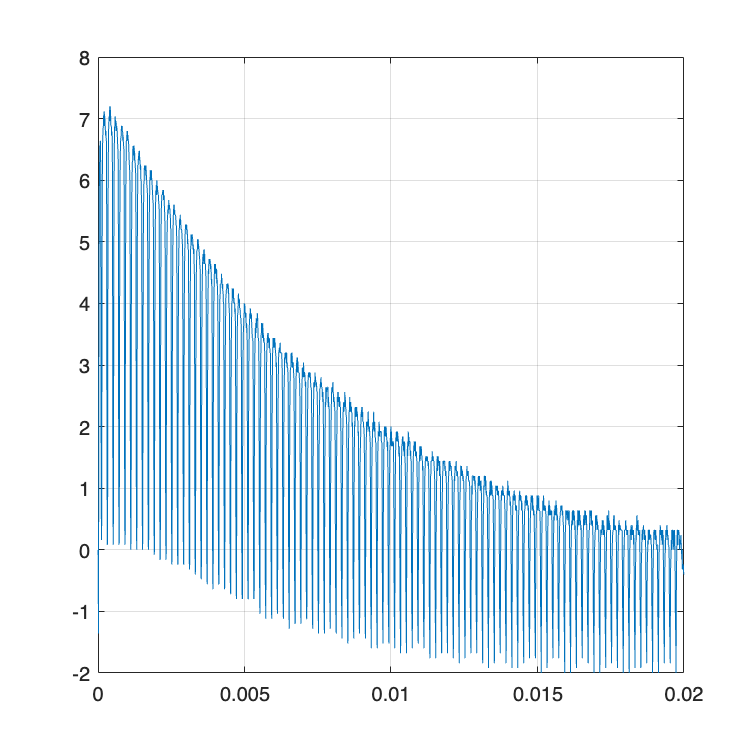


time_start =0;
time_end = 0.02;

k = find((time2>time_start)&(time2 < time_end));
time2=time2(k);
Volt2=Volt2(k);




%k = find((Volt>0));
%time=time(k);
%Volt=Volt(k)-min(Volt);



%Volt = smooth(Volt);
plot(time2,Volt2)



grid on

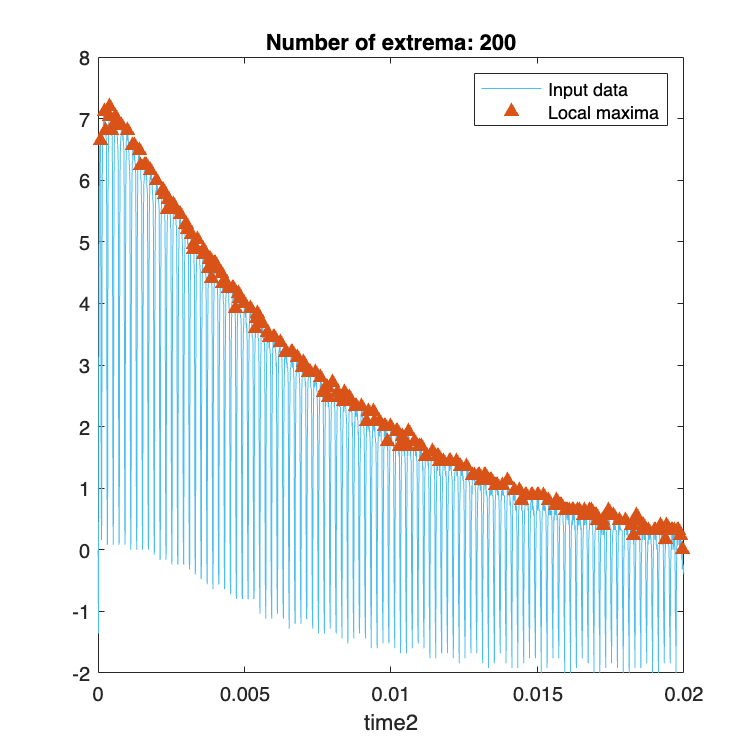

% Find local maxima
maxIndices2 = islocalmax(Volt2,"MinSeparation",2e-05,"MaxNumExtrema",200,...
    "SamplePoints",time2);

% Display results
clf
plot(time2,Volt2,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(time2(maxIndices2),Volt2(maxIndices2),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices2))
hold off
legend
xlabel("time2")

time2 = time2(maxIndices2);
Volt2 = Volt2(maxIndices2);
delta_y=Volt2.*0+1/12^0.5;
delta_x=time2.*0+0.001/12^0.5;
x=time2;
y=Volt2;
T2 = table(x,delta_x,y,delta_y)

T2 = 200×4 table
        x          delta_x       y      delta_y
    __________    __________    ____    _______

    8.0001e-05    0.00028868    6.64    0.28868
      0.000208    0.00028868    7.12    0.28868
      0.000264    0.00028868     6.8    0.28868
      0.000376    0.00028868    7.04    0.28868
        0.0004    0.00028868     7.2    0.28868
      0.000472    0.00028868     6.8    0.28868
      0.000584    0.00028868    7.04    0.28868
      0.000608    0.00028868    6.96    0.28868
       0.00064    0.00028868    6.88    0.28868
      0.000808    0.00028868    6.88    0.28868
      0.000992    0.00028868     6.8    0.28868
      0.001192    0.00028868    6.56    0.28868
      0.001232    0.00028868    6.56    0.28868
        0.0014    0.00028868    6.48    0.28868
      0.001456    0.00028868    6.24    0.28868
      0.001584    0.00028868  

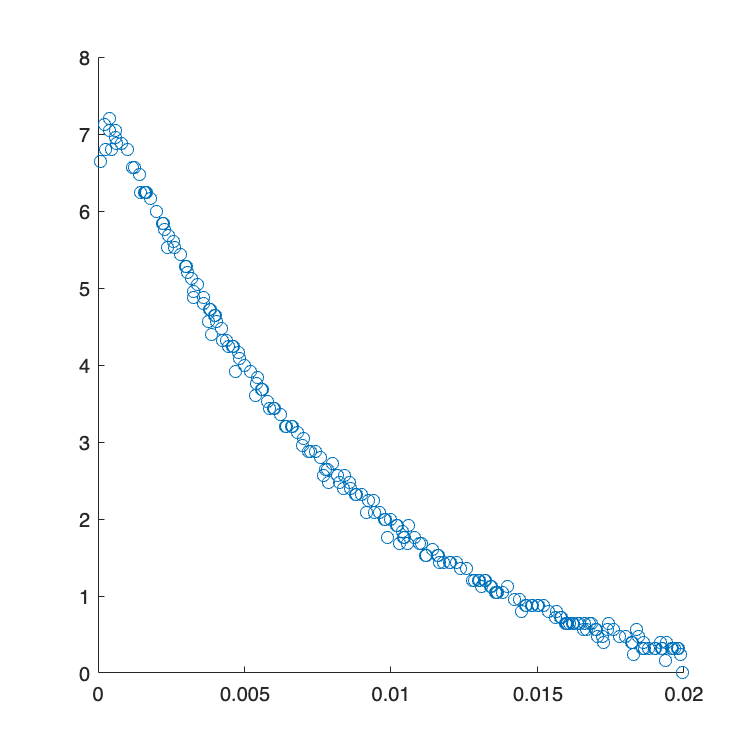

% writetable(T2,'T2_2_spinspin_err.xlsx') 




scatter(time2,Volt2)

% T2_spinspin_cap(time,Volt)
%[fitresult, gof]

# 1Per

T2_spinspin11 = readtable('1per.xlsx','Sheet','T2_spinspin')

T2_spinspin11 = 10240×2 table
      Time      CHAN1
    ________    _____

     -0.0742     -0.8
    -0.07418     -0.8
    -0.07416     -0.8
    -0.07414     -0.8
    -0.07412     -0.8
     -0.0741     -0.8
    -0.07408    -0.96
    -0.07406    -0.72
    -0.07404    -0.96
    -0.07402     -0.8
      -0.074    -0.96
    -0.07398    -1.04
    -0.07396    -0.88
    -0.07394     -0.8
    -0.07392    -0.72
     -0.0739     -0.8


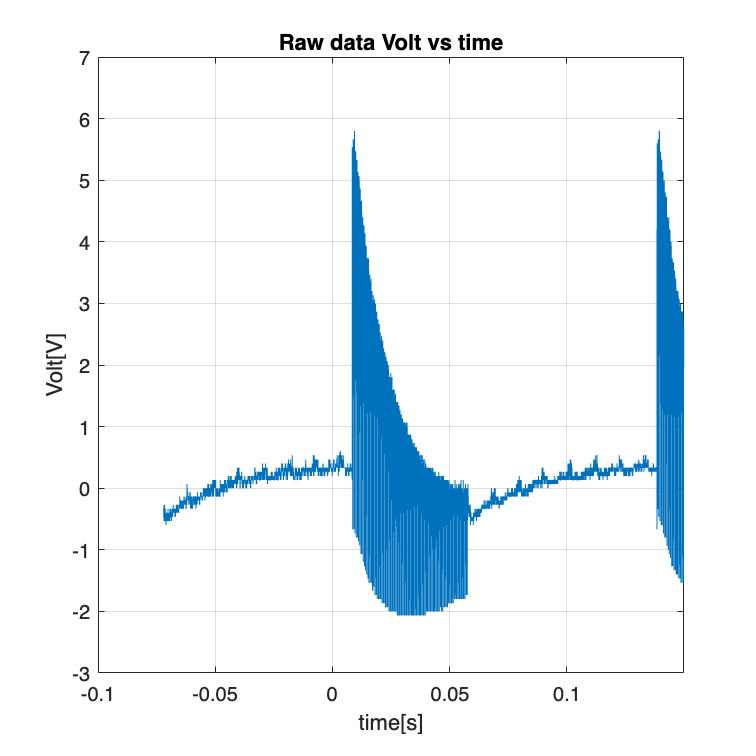

figure;
set(gcf,'position',[0,0,1000,1000])
time1=T2_spinspin11.Time;
Volt1 = T2_spinspin11.CHAN1;

plot(time1,Volt1)
ylabel('Volt[V]')
xlabel('time[s]')
title('Raw data Volt vs time')
grid on




% 
% k = find(time>0);
% time=time(k);
% Volt=Volt(k);




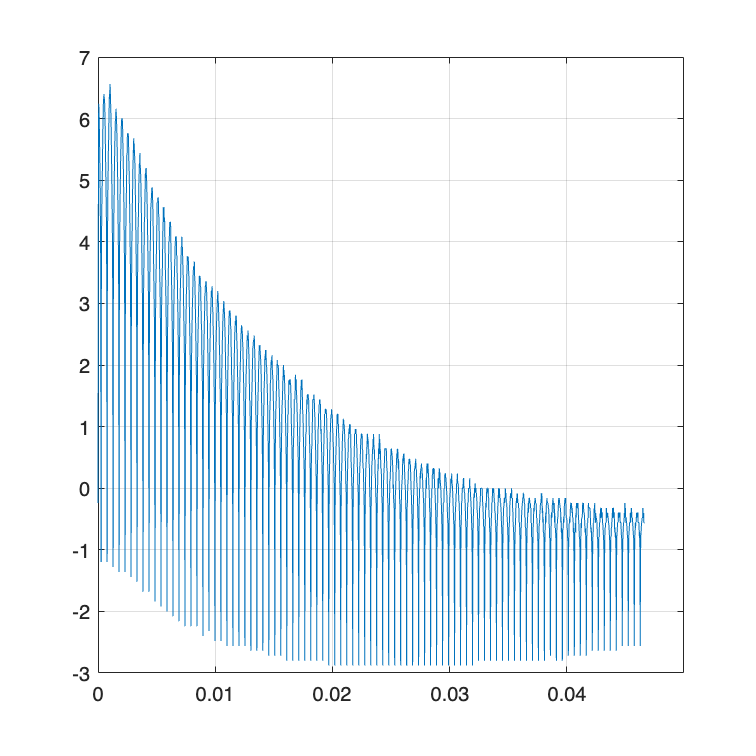


time_start =0;
time_end = 0.042;

k = find((time1>time_start)&(time1 < time_end));
time1=time1(k);
Volt1=Volt1(k);




%k = find((Volt>0));
%time=time(k);
%Volt=Volt(k)-min(Volt);



%Volt = smooth(Volt);
plot(time1,Volt1)


grid on

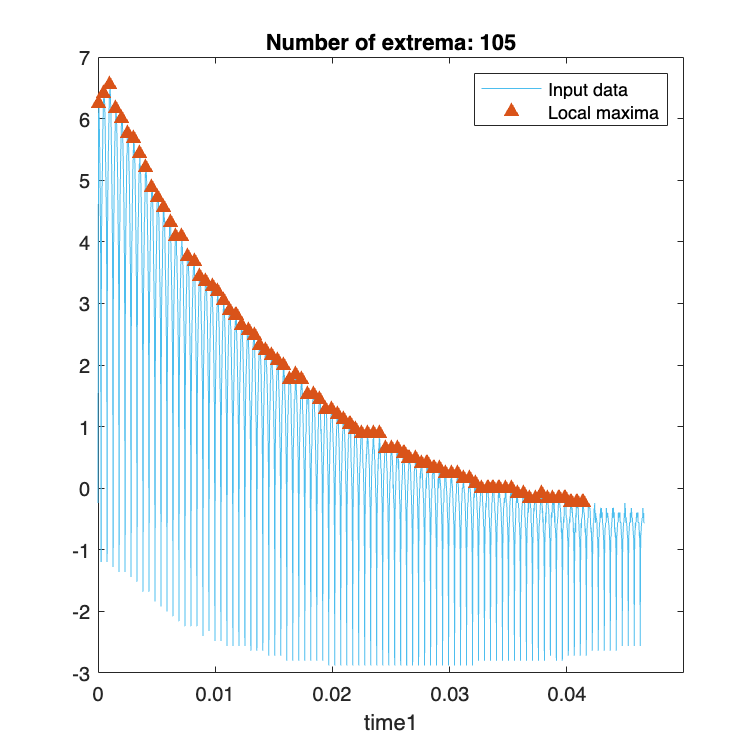

% Find local maxima
maxIndices1 = islocalmax(Volt1,"MinSeparation",2e-05,"MaxNumExtrema",105,...
    "SamplePoints",time1);

% Display results
clf
plot(time1,Volt1,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(time1(maxIndices1),Volt1(maxIndices1),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices1))
hold off
legend
xlabel("time1")

time1 = time1(maxIndices1);
Volt1 = Volt1(maxIndices1);
delta_y=Volt1.*0+1/12^0.5;
delta_x=time1.*0+0.001/12^0.5;
x=time1;
y=Volt1;
T1 = table(x,delta_x,y,delta_y)

T1 = 105×4 table
        x          delta_x       y      delta_y
    __________    __________    ____    _______

    6.0003e-05    0.00028868    6.24    0.28868
       0.00046    0.00028868     6.4    0.28868
       0.00092    0.00028868    6.56    0.28868
       0.00138    0.00028868    6.16    0.28868
       0.00184    0.00028868       6    0.28868
       0.00228    0.00028868    5.76    0.28868
       0.00274    0.00028868    5.68    0.28868
       0.00322    0.00028868    5.44    0.28868
       0.00368    0.00028868     5.2    0.28868
       0.00414    0.00028868    4.88    0.28868
        0.0046    0.00028868    4.72    0.28868
       0.00502    0.00028868    4.56    0.28868
       0.00506    0.00028868    4.56    0.28868
       0.00554    0.00028868    4.32    0.28868
       0.00598    0.00028868    4.08    0.28868
       0.00644    0.00028868  

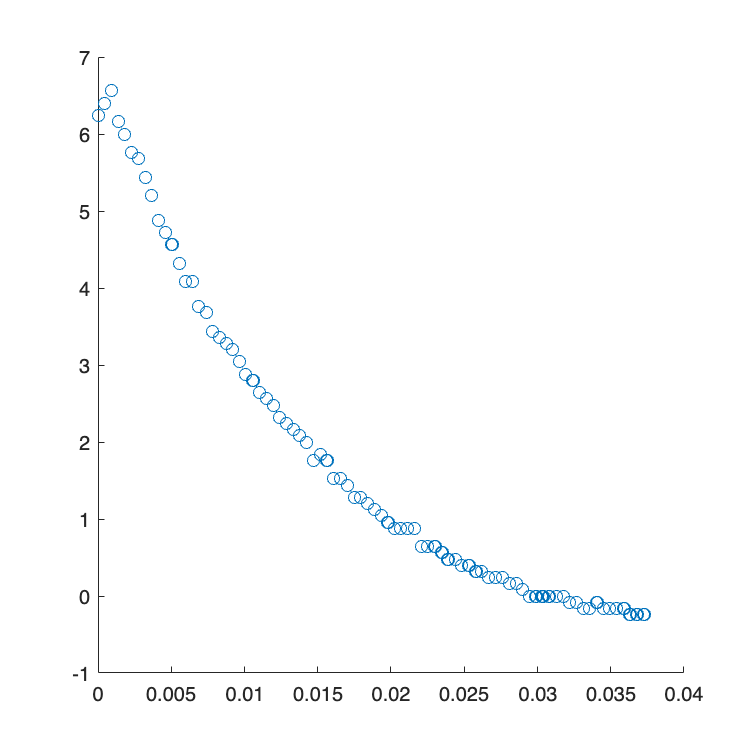

% writetable(T1,'T2_1_spinspin_err.xlsx') 


scatter(time1,Volt1)

% T2_spinspin_cap(time,Volt)
%[fitresult, gof]

# 0.5Per

T2_spinspin105 = readtable('0.5per.xlsx','Sheet','T2_spinspin')

T2_spinspin105 = 10240×2 table
      Time      CHAN1
    ________    _____

      -0.148    0.08 
    -0.14796    0.08 
    -0.14792    0.08 
    -0.14788    0.08 
    -0.14784    0.08 
     -0.1478    0.08 
    -0.14776    0.08 
    -0.14772    0.24 
    -0.14768    0.16 
    -0.14764    0.08 
     -0.1476    0.16 
    -0.14756    0.08 
    -0.14752    0.08 
    -0.14748    0.24 
    -0.14744    0.16 
     -0.1474    0.16 


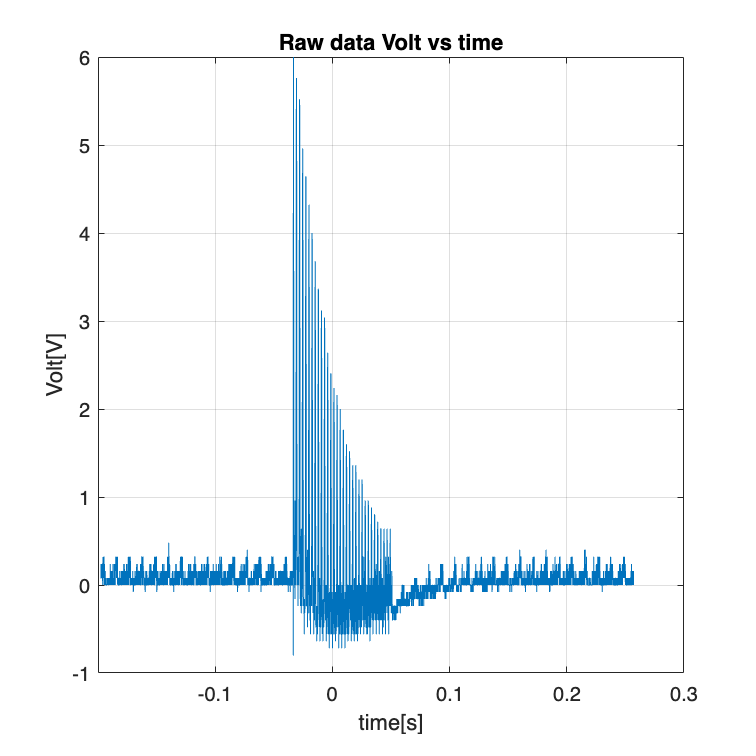

figure;
set(gcf,'position',[0,0,1000,1000])
time05=T2_spinspin105.Time;
Volt05 = T2_spinspin105.CHAN1;

plot(time05,Volt05)
ylabel('Volt[V]')
xlabel('time[s]')
title('Raw data Volt vs time')
grid on




% k = find(time>0);
% time=time(k);
% Volt=Volt(k);






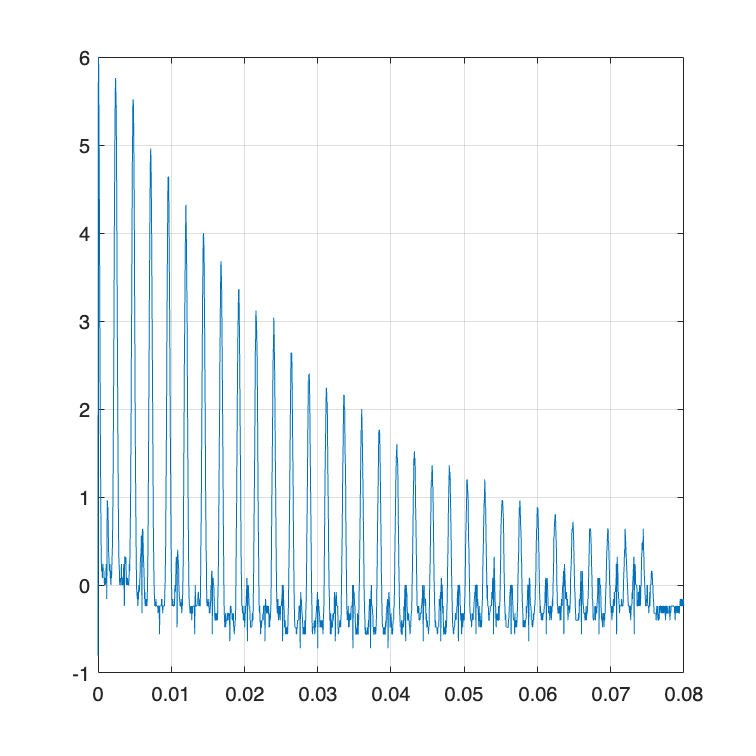


time_start =0;
time_end = 0.08;

k = find((time05>time_start)&(time05 < time_end));
time05=time05(k);
Volt05=Volt05(k);




%k = find((Volt>0));
%time=time(k);
%Volt=Volt(k)-min(Volt);



%Volt = smooth(Volt);
plot(time05,Volt05)


grid on

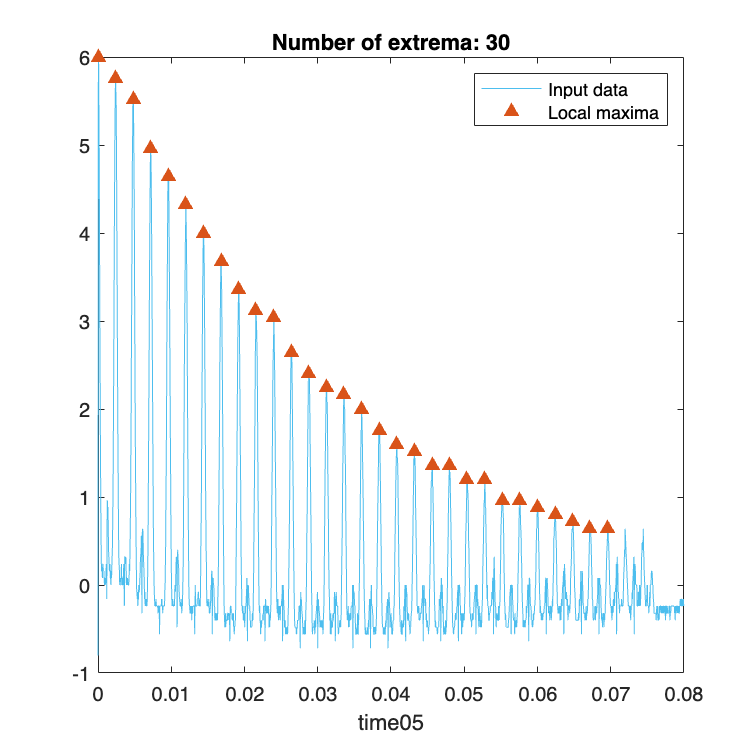

% Find local maxima
maxIndices05 = islocalmax(Volt05,"MinSeparation",2e-05,"MaxNumExtrema",30,...
    "SamplePoints",time05);

% Display results
clf
plot(time05,Volt05,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(time05(maxIndices05),Volt05(maxIndices05),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices05))
hold off
legend
xlabel("time05")

time05 = time05(maxIndices05);
Volt05 = Volt05(maxIndices05);
delta_y=Volt05.*0+1/12^0.5;
delta_x=time05.*0+0.001/12^0.5;
x=time05;
y=Volt05;
T05 = table(x,delta_x,y,delta_y)

T05 = 30×4 table
        x          delta_x       y      delta_y
    __________    __________    ____    _______

    8.0005e-05    0.00028868       6    0.28868
        0.0024    0.00028868    5.76    0.28868
        0.0048    0.00028868    5.52    0.28868
        0.0072    0.00028868    4.96    0.28868
        0.0096    0.00028868    4.64    0.28868
         0.012    0.00028868    4.32    0.28868
        0.0144    0.00028868       4    0.28868
        0.0168    0.00028868    3.68    0.28868
        0.0192    0.00028868    3.36    0.28868
       0.02156    0.00028868    3.12    0.28868
         0.024    0.00028868    3.04    0.28868
        0.0264    0.00028868    2.64    0.28868
        0.0288    0.00028868     2.4    0.28868
       0.03116    0.00028868    2.24    0.28868
       0.03356    0.00028868    2.16    0.28868
         0.036    0.00028868  

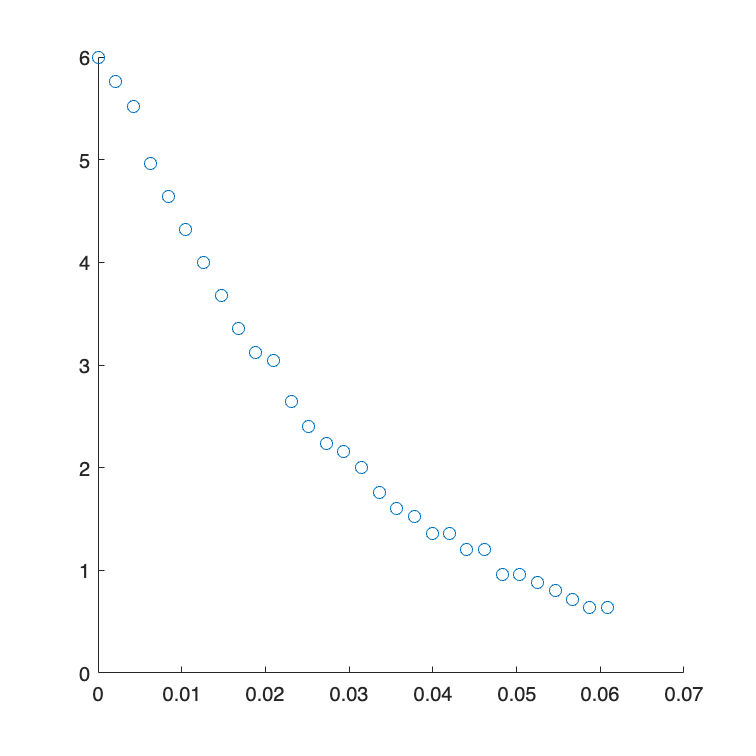

% writetable(T05,'T2_05_spinspin_err.xlsx') 

scatter(time05,Volt05)

% createFit2(time,Volt)
%[fitresult, gof]

# 0.25Per

T2_spinspin1025 = readtable('0.25per.xlsx','Sheet','T2_spinspin')

T2_spinspin1025 = 10240×2 table
      Time      CHAN1
    ________    _____

     -0.3208    -0.16
    -0.32072    -0.16
    -0.32064    -0.16
    -0.32056    -0.16
    -0.32048    -0.16
     -0.3204     -0.2
    -0.32032     -0.2
    -0.32024    -0.24
    -0.32016    -0.08
    -0.32008     -0.2
       -0.32     -0.2
    -0.31992    -0.12
    -0.31984     -0.2
    -0.31976    -0.08
    -0.31968    -0.12
     -0.3196    -0.12


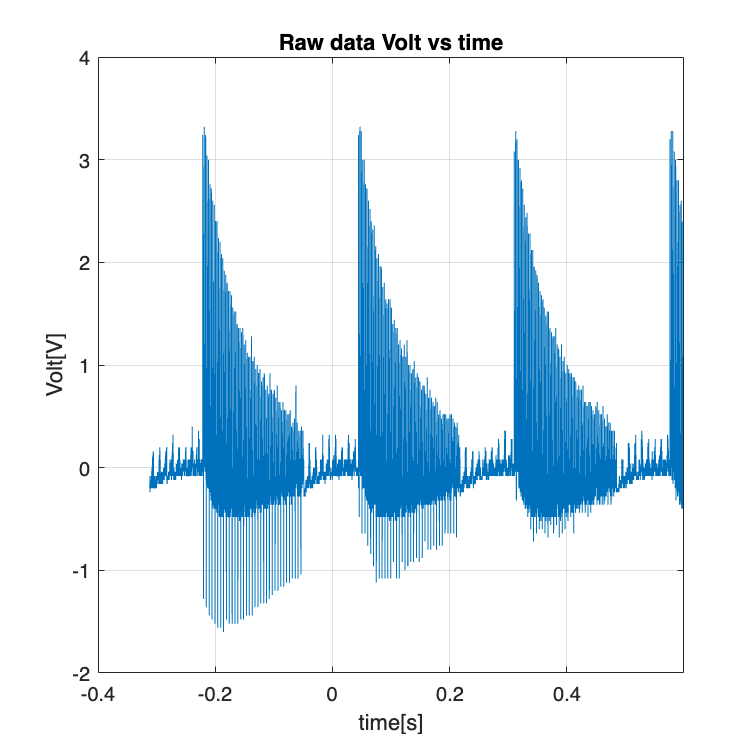

figure;
set(gcf,'position',[0,0,1000,1000])
time025=T2_spinspin1025.Time;
Volt025 = T2_spinspin1025.CHAN1;

plot(time025,Volt025)
ylabel('Volt[V]')
xlabel('time[s]')
title('Raw data Volt vs time')
grid on



% 
% k = find(time>0);
% time=time(k);
% Volt=Volt(k);



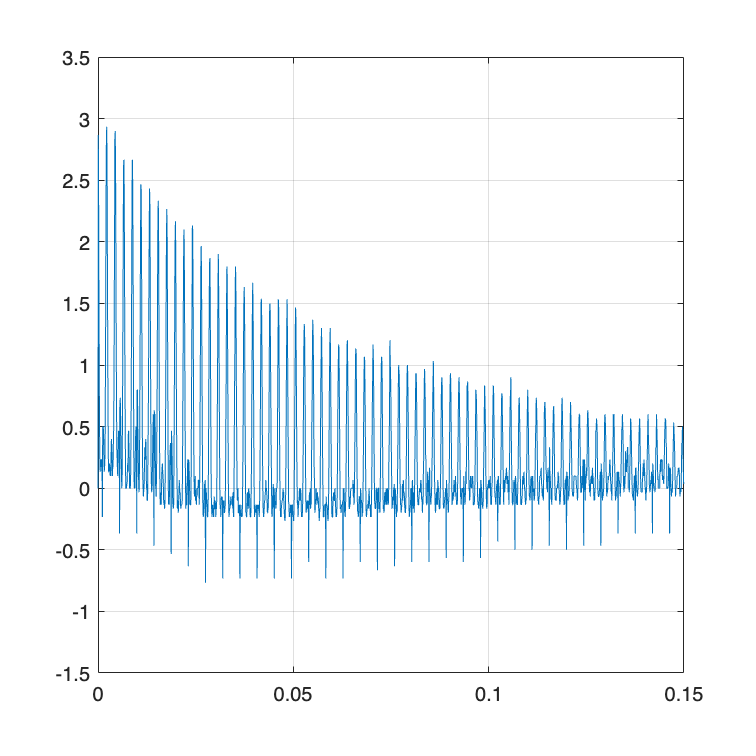


time_start =0;
time_end = 0.15;

k = find((time025>time_start)&(time025 < time_end));
time025=time025(k);
Volt025=Volt025(k);




%k = find((Volt>0));
%time=time(k);
%Volt=Volt(k)-min(Volt);



%Volt = smooth(Volt);
plot(time025,Volt025)

grid on

% Find local maxima
maxIndices025 = islocalmax(Volt025,"MinSeparation",2e-05,"MaxNumExtrema",60,...
    "SamplePoints",time025);

% Display results
clf
plot(time025,Volt025,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(time025(maxIndices025),Volt025(maxIndices025),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices025))
hold off
legend
xlabel("time025")

time025 = time025(maxIndices025);
Volt025 = Volt025(maxIndices025);
delta_y=Volt025.*0+1/12^0.5;
delta_x=time025.*0+0.001/12^0.5;
x=time025;
y=Volt025;
T025 = table(x,delta_x,y,delta_y)

T025 = 60×4 table
        x         delta_x       y      delta_y
    _________    __________    ____    _______

    8.001e-05    0.00028868    3.24    0.28868
      0.00224    0.00028868    3.32    0.28868
       0.0044    0.00028868    3.28    0.28868
      0.00664    0.00028868       3    0.28868
       0.0088    0.00028868       3    0.28868
      0.01096    0.00028868    2.76    0.28868
       0.0132    0.00028868    2.72    0.28868
      0.01544    0.00028868     2.6    0.28868
       0.0176    0.00028868    2.52    0.28868
      0.01984    0.00028868     2.4    0.28868
        0.022    0.00028868    2.32    0.28868
      0.02416    0.00028868    2.36    0.28868
       0.0264    0.00028868    2.16    0.28868
      0.02864    0.00028868    2.04    0.28868
       0.0308    0.00028868    2.08    0.28868
      0.03304    0.00028868    1.96    0.28868

% writetable(T025,'T2_025_spinspin_err.xlsx') 



scatter(time025,Volt025)

% createFit2(time,Volt)
%[fitresult, gof]

# 0.125Per

T2_spinspin10125 = readtable('0.125per.xlsx','Sheet','T2_spinspin')

T2_spinspin10125 = 600×2 table
     Time     CHAN1
    ______    _____

    -0.036       0 
    -0.035       0 
    -0.034       0 
    -0.033       0 
    -0.032       0 
    -0.031    0.24 
     -0.03       0 
    -0.029    0.24 
    -0.028    0.16 
    -0.027       0 
    -0.026       0 
    -0.025    0.24 
    -0.024       0 
    -0.023    0.16 
    -0.022    0.32 
    -0.021       0 


figure;
set(gcf,'position',[0,0,1000,1000])
time0125=T2_spinspin10125.Time;
Volt0125 = T2_spinspin10125.CHAN1;

plot(time0125,Volt0125)
ylabel('Volt[V]')
xlabel('time[s]')
title('Raw data Volt vs time')
grid on





% k = find(time>0);
% time=time(k);
% Volt=Volt(k);




time_start =0;
time_end = 0.5;

k = find((time0125>time_start)&(time0125 < time_end));
time0125=time0125(k);
Volt0125=Volt0125(k);




%k = find((Volt>0));
%time=time(k);
%Volt=Volt(k)-min(Volt);



%Volt = smooth(Volt);
plot(time0125,Volt0125)


grid on

% Find local maxima
maxIndices0125 = islocalmax(Volt0125,"MinSeparation",2e-05,"MaxNumExtrema",57,...
    "SamplePoints",time0125);

% Display results
clf
plot(time0125,Volt0125,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(time0125(maxIndices0125),Volt0125(maxIndices0125),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices0125))
hold off
legend
xlabel("time0125")

time0125 = time0125(maxIndices0125);
Volt0125 = Volt0125(maxIndices0125);
delta_y=Volt0125.*0+1/12^0.5;
delta_x=time0125.*0+0.001/12^0.5;
x=time0125;
y=Volt0125;
T0125 = table(x,delta_x,y,delta_y)

T0125 = 57×4 table
      x       delta_x       y      delta_y
    _____    __________    ____    _______

    0.003    0.00028868    4.48    0.28868
     0.01    0.00028868    4.72    0.28868
    0.018    0.00028868    4.64    0.28868
    0.026    0.00028868    4.32    0.28868
    0.034    0.00028868    4.24    0.28868
    0.042    0.00028868    3.92    0.28868
     0.05    0.00028868    3.68    0.28868
    0.057    0.00028868    3.36    0.28868
    0.066    0.00028868     3.2    0.28868
    0.074    0.00028868    3.04    0.28868
    0.082    0.00028868    2.96    0.28868
     0.09    0.00028868     2.8    0.28868
    0.098    0.00028868    2.72    0.28868
    0.106    0.00028868    2.64    0.28868
    0.114    0.00028868    2.64    0.28868
    0.122    0.00028868    2.48    0.28868



% writetable(T0125,'T2_0125_spinspin_err.xlsx') 

scatter(time0125,Volt0125)

% createFit2(time,Volt)
%[fitresult, gof]

# 0per

T2_spinspin10 = readtable('0per.xlsx','Sheet','T2_spinspin')

T2_spinspin10 = 10240×2 table
      Time         CHAN1   
    ________    ___________

      -0.192          -0.08
    -0.19177          -0.08
    -0.19153          -0.08
     -0.1913          -0.08
    -0.19106          -0.08
    -0.19083    -1.3878e-16
    -0.19059          -0.08
    -0.19036          -0.08
    -0.19012    -1.3878e-16
    -0.18989    -1.3878e-16
    -0.18966           0.08
    -0.18942          -0.08
    -0.18919    -1.3878e-16
    -0.18895          -0.08
    -0.18872    -1.3878e-16
    -0.18848          -0.08


figure;
set(gcf,'position',[0,0,1000,1000])
time0=T2_spinspin10.Time;
Volt0 = T2_spinspin10.CHAN1;

plot(time0,Volt0)
ylabel('Volt[V]')
xlabel('time[s]')

grid on
title('Raw data Volt vs time')




% 
% k = find(time>0);
% time=time(k);
% Volt=Volt(k);







time_start =0;
time_end = 1.5;

k = find((time0>time_start)&(time0 < time_end));
time0=time0(k);
Volt0=Volt0(k);




%k = find((Volt>0));
%time=time(k);
%Volt=Volt(k)-min(Volt);



%Volt = smooth(Volt);
plot(time0,Volt0)


grid on

% Find local maxima
maxIndices0 = islocalmax(Volt0,"MaxNumExtrema",60,"SamplePoints",time0);

% Display results
clf
plot(time0,Volt0,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(time0(maxIndices0),Volt0(maxIndices0),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices0))
hold off
legend
xlabel("time0")

time0 = time0(maxIndices0);
Volt0 = Volt0(maxIndices0);

delta_y=Volt0.*0+1/12^0.5;
delta_x=time0.*0+0.001/12^0.5;

x=time0;
y=Volt0;


T0 = table(x,delta_x,y,delta_y)

T0 = 60×4 table
       x         delta_x       y      delta_y
    ________    __________    ____    _______

    0.023882    0.00028868     9.6    0.28868
    0.047791    0.00028868    9.52    0.28868
    0.071934    0.00028868       8    0.28868
    0.095843    0.00028868    9.04    0.28868
     0.11975    0.00028868     7.6    0.28868
      0.1439    0.00028868    7.84    0.28868
      0.1678    0.00028868    7.84    0.28868
     0.19195    0.00028868    6.48    0.28868
     0.21586    0.00028868    7.68    0.28868
     0.23976    0.00028868    6.72    0.28868
     0.26391    0.00028868     6.8    0.28868
     0.28782    0.00028868     6.8    0.28868
     0.31196    0.00028868    5.84    0.28868
     0.33587    0.00028868     6.4    0.28868
     0.35978    0.00028868    5.44    0.28868
     0.38392    0.00028868    5.68    0.28868


% writetable(T0,'T2_0_spinspin_err.xlsx') 



scatter(time0,Volt0)

% T2_spinspin_cap(time,Volt)
%[fitresult, gof]

# Gly

T2_spinspin1gly = readtable('gly.xlsx','Sheet','T2_spinspin')

T2_spinspin1gly = 10240×2 table
      Time      CHAN1
    ________    _____

      -0.156    -0.24
    -0.15596    -0.24
    -0.15592    -0.24
    -0.15588    -0.24
    -0.15584    -0.24
     -0.1558    -0.24
    -0.15576    -0.24
    -0.15572    -0.32
    -0.15568    -0.32
    -0.15564    -0.32
     -0.1556    -0.24
    -0.15556    -0.32
    -0.15552     -0.4
    -0.15548    -0.32
    -0.15544    -0.32
     -0.1554    -0.24


figure;
set(gcf,'position',[0,0,1000,1000])
timeg=T2_spinspin1gly.Time;
Voltg = T2_spinspin1gly.CHAN1;

plot(timeg,Voltg)
ylabel('Volt[V]')
xlabel('time[s]')
title('Raw data Volt vs time');grid on


% 
% 
% k = find(time>0);
% time=time(k);
% Volt=Volt(k);





time_start =0;
time_end = 0.08;

k = find((timeg>time_start)&(timeg < time_end));
timeg=timeg(k);
Voltg=Voltg(k);




%k = find((Volt>0));
%time=time(k);
%Volt=Volt(k)-min(Volt);



%Volt = smooth(Volt);
plot(timeg,Voltg)


grid on

% Find local maxima
maxIndicesg = islocalmax(Voltg,"MaxNumExtrema",47,"SamplePoints",timeg);

% Display results
clf
plot(timeg,Voltg,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(timeg(maxIndicesg),Voltg(maxIndicesg),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndicesg))
hold off
legend
xlabel("timeg")

timeg = timeg(maxIndicesg);
Voltg = Voltg(maxIndicesg);
delta_y=Voltg.*0+1/12^0.5;
delta_x=timeg.*0+0.001/12^0.5;
x=timeg;
y=Voltg;
Tg = table(x,delta_x,y,delta_y)

Tg = 47×4 table
        x          delta_x       y      delta_y
    __________    __________    ____    _______

    8.0005e-05    0.00028868       4    0.28868
        0.0014    0.00028868    4.08    0.28868
       0.00276    0.00028868       4    0.28868
        0.0042    0.00028868    3.76    0.28868
        0.0056    0.00028868     3.6    0.28868
         0.007    0.00028868    3.44    0.28868
        0.0084    0.00028868    3.36    0.28868
        0.0098    0.00028868    3.12    0.28868
        0.0112    0.00028868    3.04    0.28868
        0.0126    0.00028868    2.88    0.28868
         0.014    0.00028868     2.8    0.28868
        0.0154    0.00028868    2.64    0.28868
       0.01684    0.00028868    2.64    0.28868
        0.0182    0.00028868    2.56    0.28868
        0.0196    0.00028868    2.32    0.28868
         0.021    0.00028868   


% writetable(Tg,'T2_gly_spinspin_err.xlsx') 

scatter(timeg,Voltg)

% createFit2(time,Volt)
%[fitresult, gof]


# unknown

T2_spinspin1u = readtable('unknown.xlsx','Sheet','T2_spinspin')

T2_spinspin1u = 10240×2 table
      Time      CHAN1
    ________    _____

        -0.3     1.2 
    -0.29994     1.2 
    -0.29988     1.2 
    -0.29982     1.2 
    -0.29977     1.2 
    -0.29971     1.2 
    -0.29965     1.4 
    -0.29959     1.2 
    -0.29953     1.2 
    -0.29947     1.2 
    -0.29941     1.4 
    -0.29936     1.4 
     -0.2993     1.4 
    -0.29924     1.4 
    -0.29918     1.4 
    -0.29912     1.2 


figure;
set(gcf,'position',[0,0,1000,1000])
timeu=T2_spinspin1u.Time;
Voltu = T2_spinspin1u.CHAN1;

plot(timeu,Voltu)
ylabel('Volt[V]')
xlabel('time[s]')
title('Raw data Volt vs time');grid on


% 
% 
% k = find(time>0);
% time=time(k);
% Volt=Volt(k);





time_start =0;
time_end = 0.2;

k = find((timeu>time_start)&(timeu < time_end));
timeu=timeu(k);
Voltu=Voltu(k);




%k = find((Volt>0));
%time=time(k);
%Volt=Volt(k)-min(Volt);



%Volt = smooth(Volt);
plot(timeu,Voltu)


grid on

% Find local maxima
maxIndicesu = islocalmax(Voltu,"MaxNumExtrema",70,"SamplePoints",timeu);

% Display results
clf
plot(timeu,Voltu,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(timeu(maxIndicesu),Voltu(maxIndicesu),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndicesu))
hold off
legend
xlabel("timeu")


timeu = timeu(maxIndicesu);
Voltu = Voltu(maxIndicesu);
delta_y=Voltu.*0+1/12^0.5;
delta_x=timeu.*0+0.001/12^0.5;
x=timeu;
y=Voltu;
Tu = table(x,delta_x,y,delta_y)

Tu = 70×4 table
        x         delta_x       y     delta_y
    _________    __________    ___    _______

    0.0016799    0.00028868    9.2    0.28868
    0.0034962    0.00028868    9.2    0.28868
    0.0052539    0.00028868    8.6    0.28868
    0.0071288    0.00028868    8.6    0.28868
    0.0088865    0.00028868    7.8    0.28868
     0.010703    0.00028868    7.6    0.28868
     0.012519    0.00028868    7.4    0.28868
     0.014277    0.00028868    7.2    0.28868
     0.016093    0.00028868    6.8    0.28868
     0.017851    0.00028868    6.4    0.28868
     0.019726    0.00028868    6.4    0.28868
     0.021483    0.00028868    6.2    0.28868
       0.0233    0.00028868    5.8    0.28868
     0.025116    0.00028868    5.6    0.28868
     0.026874    0.00028868    5.4    0.28868
      0.02869    0.00028868    5.2    0.28868



% writetable(Tu,'T2_u_spinspin_err.xlsx') 

scatter(x,y)

figure;

scatter(time8,Volt8/max(Volt8));legend '8'
hold on

a=0.5348;
b= 425.267;
c=7.250e-3;

fit8 = a.*exp(-b.*(time8-c))

fit8 =    11.3988
   10.6128
    9.7475
    9.6485
    8.9527
    8.8317
    8.0292
    7.8136
    7.4249
    7.2997


plot(time8,fit8/max(fit8))
hold on


scatter(time4,Volt4/max(Volt4));legend '4'
hold on

a=9.944 ;
b=162.914 ;
c=-5.197e-4;

fit4 = a.*exp(-b.*(time4-c))

fit4 =     9.0302
    8.8438
    8.5827
    8.3509
    8.0832
    7.9061
    7.6327
    7.4460
    7.2450
    7.1792


plot(time4,fit4/max(fit4))
hold on

scatter(time2,Volt2/max(Volt2));legend '2'
hold on

a=9.994;
b=142.693;
c=-1.679e-3;

fit2 = a.*exp(-b.*(time2-c))

fit2 =     7.7756
    7.6348
    7.5741
    7.4540
    7.4285
    7.3526
    7.2360
    7.2113
    7.1784
    7.0084


plot(time2,fit2/max(fit2))
hold on

scatter(time1,Volt1/max(Volt1));legend '1'
hold on

a=10.03;
b=101.134;
c=-3.029e-3;

fit1 = a.*exp(-b.*(time1-c))

fit1 =     7.3388
    7.0479
    6.7275
    6.4217
    6.1298
    5.8630
    5.5965
    5.3313
    5.0890
    4.8576


plot(time1,fit1/max(fit1))
hold on

scatter(time05,Volt05/max(Volt05));legend '0.5'
hold on

a=11.13;
b=32.3756;
c=-0.01776;

fit05 = a.*exp(-b.*(time05-c))

fit05 =     6.2468
    5.7947
    5.3615
    4.9607
    4.5899
    4.2467
    3.9292
    3.6355
    3.3637
    3.1163


plot(time05,fit05/max(fit05))
hold on

scatter(time025,Volt025/max(Volt025));legend '0.25'
hold on

a= 8.304;
b=14.7007;
c=-0.06322;

fit025 = a.*exp(-b.*(time025-c))

fit025 =     3.2746
    3.1722
    3.0731
    2.9735
    2.8806
    2.7906
    2.7002
    2.6127
    2.5310
    2.4490


plot(time025,fit025/max(fit025))
hold on

scatter(time0125,Volt0125/max(Volt0125));legend '0.125'
hold on

a=10.69;
b=4.85313;
c=-0.1711;

fit0125 = a.*exp(-b.*(time0125-c))

fit0125 =     4.5923
    4.4389
    4.2699
    4.1073
    3.9509
    3.8004
    3.6557
    3.5336
    3.3826
    3.2537


plot(time0125,fit0125/max(fit0125))
hold on

scatter(time0,Volt0/max(Volt0));legend '0'
hold on

a=8.785;
b=1.30568;
c=0.05976;

fit0 = a.*exp(-b.*(time0-c))

fit0 =     9.2063
    8.9234
    8.6465
    8.3807
    8.1231
    7.8711
    7.6291
    7.3924
    7.1652
    6.9450


plot(time0,fit0/max(fit0))
hold on

scatter(timeg,Voltg/max(Voltg));legend 'gly'
hold on

a= 8.264;
b=30.3938;
c=-0.02197;

fitg = a.*exp(-b.*(timeg-c))

fitg =     4.2280
    4.0617
    3.8972
    3.7304
    3.5750
    3.4260
    3.2833
    3.1465
    3.0154
    2.8898


plot(timeg,fitg/max(fitg))
hold on

scatter(timeu,Voltu/max(Voltu));legend 'unknown'
hold on

a=4.265;
b=14.8681;
c=0.04786;

fitu = a.*exp(-b.*(timeu-c))

fitu =     8.4744
    8.2486
    8.0359
    7.8149
    7.6134
    7.4105
    7.2131
    7.0270
    6.8398
    6.6634


plot(timeu,fitu/max(fitu))
hold on

legend('$8\% data$','$8\% fiit$','$4\% data$','$4\% fiit$',...
    '$2\% data$','$2\% fiit$','$1\% data$','$1\% fiit$',...
    '$0.5\% data$','$0.5\% fiit$','$0.25\% data$','$0.25\% fiit$',...
    '$0.125\% data$','$0.125\% fiit$',...
    '$0\% data$','$0\% fiit$','gly data','gly fit',...
    'unknown data','unknown fit','interpreter','latex')

xlabel('time[sec]','FontSize',16,'Interpreter','latex')
ylabel('Volt[norm \#]','FontSize',16,'Interpreter','latex')
title('T2 spin spin - Volt vs. time','FontSize',16,'Interpreter','latex')
grid on

title("T2 spin spin data/fit - Volt vs. time")

% figure;
% res_t2=[1/386.23,1/157.93,1/141.233,1/101.135,1/32.3756,1/14.7756,1/5.11397];
% per=[8,4,2,1,0.5,0.25,0.125];
% scatter(per,res_t2)
% set(gca, 'XDir','reverse')
% xlabel('Per %')

% T2_power_per_T2(per, res_t2)
% 
% xlabel("%")
% ylabel("T2_spin spin [sec]")

pm = readtable('T2_8_CMspinspin_err.xlsx')

pm = 35×4 table
        x          delta_x       y     delta_y
    __________    __________    ___    _______

    7.6001e-05    0.00028868    9.4    0.28868
      0.000152    0.00028868    9.6    0.28868
      0.000328    0.00028868    8.6    0.28868
      0.000468    0.00028868    7.6    0.28868
       0.00052    0.00028868    7.4    0.28868
       0.00064    0.00028868    6.4    0.28868
       0.00066    0.00028868    6.2    0.28868
      0.000796    0.00028868    5.8    0.28868
      0.000832    0.00028868    5.8    0.28868
      0.000988    0.00028868    4.4    0.28868
      0.001092    0.00028868    4.4    0.28868
       0.00112    0.00028868    4.6    0.28868
      0.001172    0.00028868    4.2    0.28868
      0.001292    0.00028868    3.6    0.28868
      0.001332    0.00028868    3.6    0.28868
      0.001356    0.00028868    3.6    0.28868


cpmp = readtable('T2_8_spinspin_err.xlsx')

cpmp = 35×4 table
        x          delta_x       y      delta_y
    __________    __________    ____    _______

    5.6001e-05    0.00028868    10.6    0.28868
      0.000224    0.00028868    10.6    0.28868
      0.000424    0.00028868     9.6    0.28868
      0.000448    0.00028868     9.6    0.28868
      0.000624    0.00028868     8.8    0.28868
      0.000656    0.00028868     8.8    0.28868
       0.00088    0.00028868       8    0.28868
      0.000944    0.00028868     7.8    0.28868
      0.001064    0.00028868     7.6    0.28868
      0.001104    0.00028868     7.4    0.28868
       0.00132    0.00028868     6.6    0.28868
      0.001504    0.00028868     6.2    0.28868
      0.001536    0.00028868     6.2    0.28868
       0.00176    0.00028868     5.6    0.28868
      0.001824    0.00028868     5.4    0.28868
      0.001944    0.00028868 

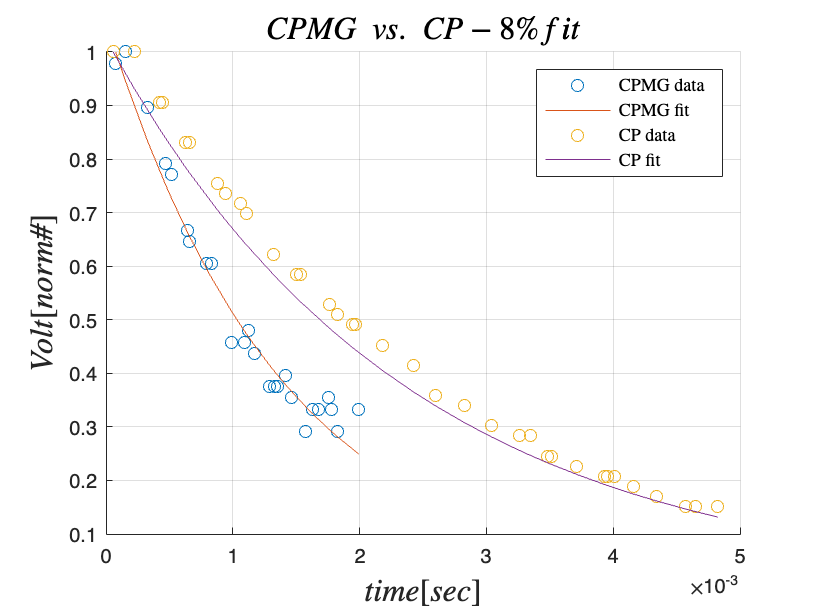


figure;
timepm = pm.x(1:25,1);
voltpm=pm.y(1:25,1)/max(pm.y(1:25,1));
timecmpm = cpmp.x;
voltcpmp = cpmp.y/max(cpmp.y);

a=30.61;
b= 724.65;
c=-1.499e-3;


fitcp = a.*exp(-b.*(timepm-c))/max(a.*exp(-b.*(timepm-c)));

a=0.5348;
b= 425.267;
c=7.250e-3;

fitpm = a.*exp(-b.*(timecmpm-c))/max(a.*exp(-b.*(timecmpm-c)));


scatter(timepm,voltpm)
hold on
plot(timepm,fitcp)
hold on
scatter(timecmpm,voltcpmp)
hold on
plot(timecmpm,fitpm)
legend('CPMG data','CPMG fit','CP data','CP fit','interpreter','latex')
title('$CPMG\ vs.\ CP - 8\% fiit$','Interpreter','latex','FontSize',16)
xlabel('$time[sec]$','Interpreter','latex','FontSize',16)
ylabel('$Volt[norm \#]$','Interpreter','latex','FontSize',16)
grid on